

dir_name = "22";
folder_path = fullfile('test_images', dir_name);

file_pattern = fullfile(folder_path, 'line_*_points.csv');
files = dir(file_pattern);

if isempty(files)
    error('Файлы не найдены в папке: %s', folder_path);
end

figure('Position', [100, 100, 1200, 800]);
hold on; 
grid on; 
axis equal;

colors = parula(max(length(files), 2));

for i = 1:length(files)
    try
        filepath = fullfile(folder_path, files(i).name);
        data = readtable(filepath);
        
        line_id = data.line_id(1);
        x = data.x;
        y = data.y;
        
        % Рисуем линию
        plot(x, y, 'o-', 'Color', colors(i,:), ...
            'LineWidth', 1.5, 'MarkerSize', 2, ...
            'DisplayName', sprintf('Line %d', line_id));
        
        % ========== ДОБАВЛЯЕМ ПОДПИСЬ В КОНЦЕ ЛИНИИ ==========
        % Берём последнюю точку линии
        last_x = x(end);
        last_y = y(end);
        
        % Добавляем текст рядом с последней точкой
        text(last_x, last_y, sprintf('  %d', line_id), ...
            'FontSize', 10, 'FontWeight', 'bold', ...
            'Color', colors(i,:), ...
            'VerticalAlignment', 'middle', ...
            'HorizontalAlignment', 'left');
        
        fprintf('✓ %s (Line %d)\n', files(i).name, line_id);
        
    catch ME
        fprintf('✗ %s: %s\n', files(i).name, ME.message);
    end
end

✓ line_0_points.csv (Line 0)
✓ line_10_points.csv (Line 10)
✓ line_11_points.csv (Line 11)
✓ line_12_points.csv (Line 12)
✓ line_13_points.csv (Line 13)
✓ line_14_points.csv (Line 14)
✓ line_1_points.csv (Line 1)
✓ line_2_points.csv (Line 2)
✓ line_3_points.csv (Line 3)
✓ line_4_points.csv (Line 4)
✓ line_5_points.csv (Line 5)
✓ line_6_points.csv (Line 6)
✓ line_7_points.csv (Line 7)
✓ line_8_points.csv (Line 8)
✓ line_9_points.csv (Line 9)


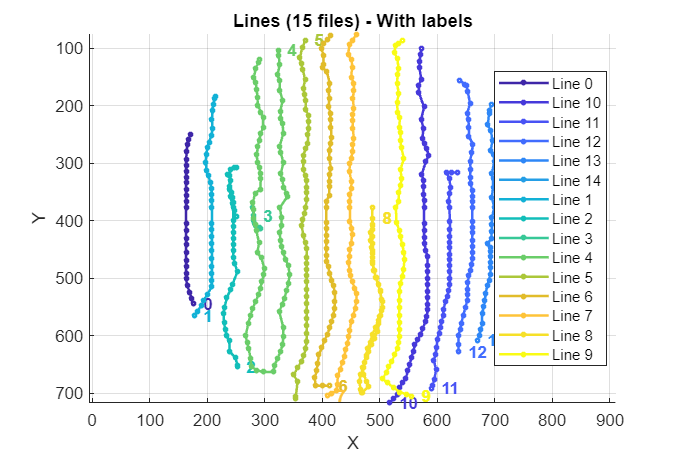


xlabel('X'); 
ylabel('Y');
title(sprintf('Lines (%d files) - With labels', length(files)));
legend('Location', 'best', 'FontSize', 9);
set(gca, 'YDir', 'reverse');

hold off;